## Question 2

Question 2A:

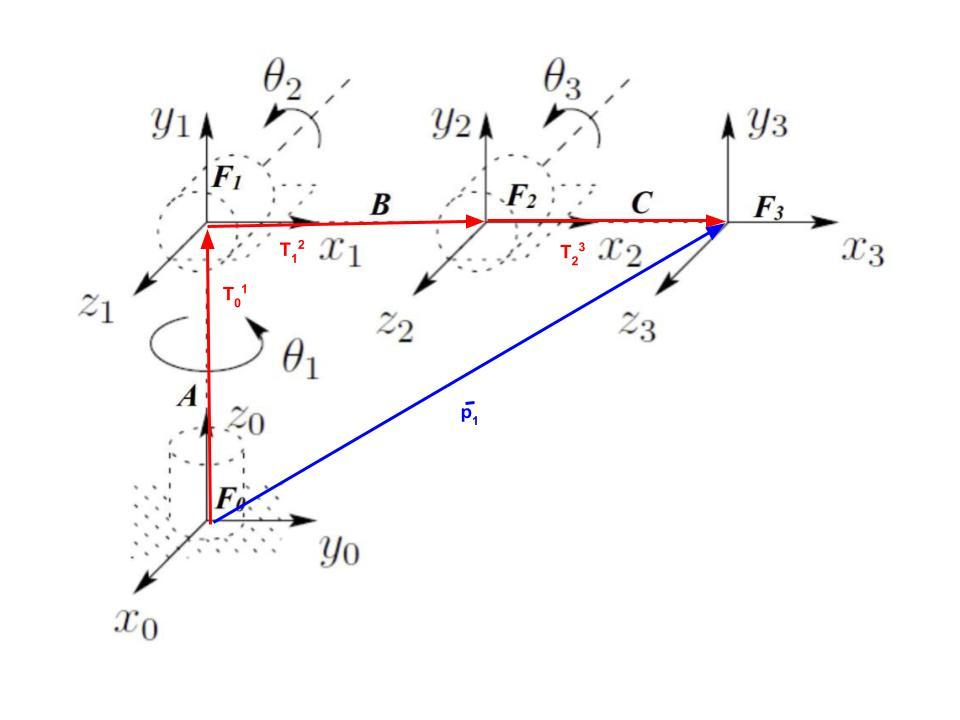

Question 2B: 

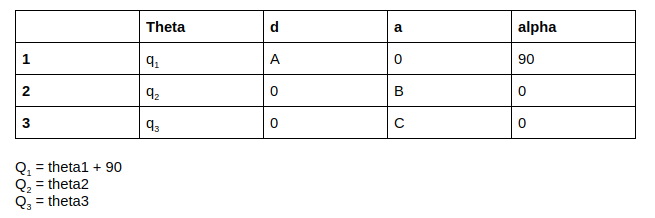

Question 2C: Write a matlab function that takes the 4 DH parameters from a given link and outputs the corresponding symbolic transformation matrix. 

%Note, angle input in Radians. Function is commented out due to matlab syntax. It can be found uncommented at the end of the file. 
% function T = DHTrans(theta, d, a, alpha)
% T = [cos(theta)    -sin(theta)*cos(alpha)    sin(theta)*sin(alpha)     a*cos(theta) ;
%      sin(theta)    cos(theta)*cos(alpha)     -cos(theta)*sin(alpha)    a*sin(theta);
%      0             sin(alpha)                cos(alpha)                d;
%      0             0                         0                         1];
% end

Question 2D : Determine each of the 3 intermediate homogenous 4x4 transformation matrices. These should be symbolic.

%q1 = theta1 + 90
%q2 = theta2
%q3 = theta3

% T01 = [cos(q1)  -sin(q1)*cos(alpha1)  sin(q1)*sin(alpha1)   a1*cos(q1) ;
%        sin(q1)  cos(q1)*cos(alpha1)   -cos(q1)*sin(alpha1)  a1*sin(q1) ;
%        0        sin(alpha1)           cos(alpha1)           d1 ;
%        0        0                     0                     1]

% T12 = [cos(q2)  -sin(q2)*cos(alpha2)  sin(q2)*sin(alpha2)   a2*cos(q2) ;
%        sin(q2)  cos(q2)*cos(alpha2)   -cos(q2)*sin(alpha2)  a2*sin(q2) ;
%        0        sin(alpha2)           cos(alpha2)           0 ;
%        0        0                     0                     1]

% T23 = [cos(q3)  -sin(q3)*cos(alpha3)  sin(q3)*sin(alpha3)   C*cos(q3) ;
%        sin(q3)  cos(q3)*cos(alpha3)   -cos(q3)*sin(alpha3)  C*sin(q3) ;
%        0        sin(alpha3)           cos(alpha3)           0 ;
%        0        0                     0                     1]

Question 2E: Determine the robot's forward kinematics (T03).

%T03 = T01*T12*T23

Question 2F:

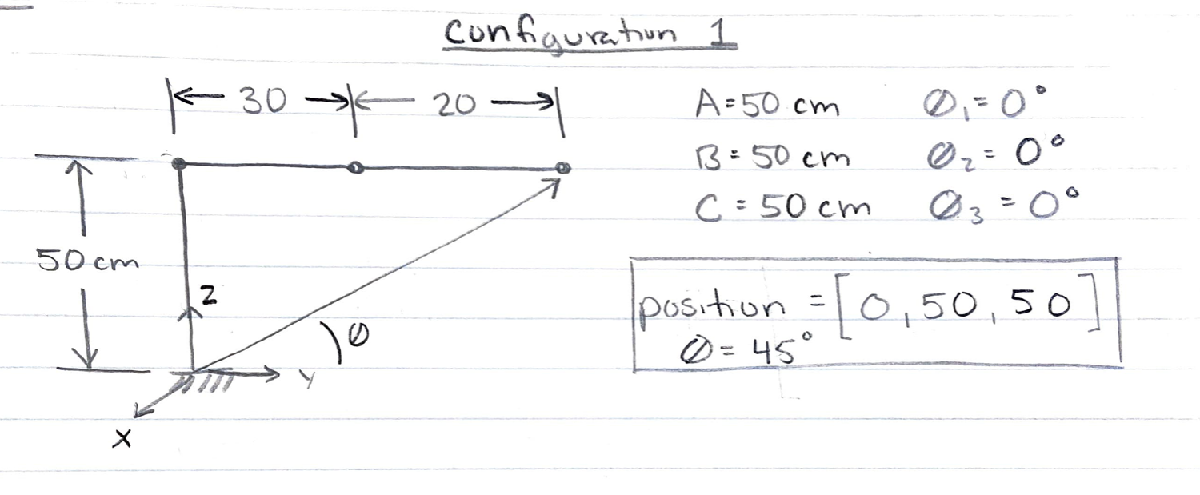

%Question 2G: Numerically solve for the three intermediate transformation matrices of Part 2.d and then numerically solve for the transformation matrix of Part 2.e representing the robot’s forward kinematics as a 4x4 numeric homogeneous transformation matrix for the following configurations:

#### Configuration 1

theta1 = 0 + 90;
theta2 = 0;
theta3 = 0;

A = 50;
d2 = 0;
d3 = 0;

a1 = 0;
B=30;
C=20;

alpha1 = 90;
alpha2 = 0;
alpha3 = 0;

disp('Transformation 0 to 1 (config 1)');

Transformation 0 to 1 (config 1)


T01 = DHTrans(theta1, A, a1, alpha1);
disp(T01);

     0     0     1     0
     1     0     0     0
     0     1     0    50
     0     0     0     1




disp('Transformation 1 to 2 (config 1)');

Transformation 1 to 2 (config 1)


T12 = DHTrans(theta2, d2, B, alpha2);
disp(T12);

     1     0     0    30
     0     1     0     0
     0     0     1     0
     0     0     0     1




disp('Transformation 2 to 3 (config 1)');

Transformation 2 to 3 (config 1)


T23 = DHTrans(theta3, d3, C, alpha3);
disp(T23);

     1     0     0    20
     0     1     0     0
     0     0     1     0
     0     0     0     1




disp('Transformation 0 to 3 (config 1)');

Transformation 0 to 3 (config 1)


T03 = T01*T12*T23;
disp(T03);

     0     0     1     0
     1     0     0    50
     0     1     0    50
     0     0     0     1



#### Configuration 2

theta1 = 45+90;
theta2 = 30;
theta3 = -30;
A = 50;
d2 = 0;
d3 = 0;
a1 = 0;
B=30;
C=20;
alpha1 = 90;
alpha2 = 0;
alpha3 = 0;

disp('Transformation 0 to 1 (config 2)');

Transformation 0 to 1 (config 2)


T01 = DHTrans(theta1, A, a1, alpha1);
disp(T01);

   -0.7071         0    0.7071         0
    0.7071         0    0.7071         0
         0    1.0000         0   50.0000
         0         0         0    1.0000




disp('Transformation 1 to 2 (config 2)');

Transformation 1 to 2 (config 2)


T12 = DHTrans(theta2, d2, B, alpha2);
disp(T12);

    0.8660   -0.5000         0   25.9808
    0.5000    0.8660         0   15.0000
         0         0    1.0000         0
         0         0         0    1.0000




disp('Transformation 2 to 3 (config 2)');

Transformation 2 to 3 (config 2)


T23 = DHTrans(theta3, d3, C, alpha3);
disp(T23);

    0.8660    0.5000         0   17.3205
   -0.5000    0.8660         0  -10.0000
         0         0    1.0000         0
         0         0         0    1.0000




disp('Transformation 0 to 3 (config 2)');

Transformation 0 to 3 (config 2)


T03 = T01*T12*T23;
disp(T03);

   -0.7071         0    0.7071  -32.5133
    0.7071         0    0.7071   32.5133
         0    1.0000         0   65.0000
         0         0         0    1.0000



%When comparing these 2 configurations, both configurations are in the same final position. Both are at a coordinate of [ 0 50 50] relative to the initial frame. 

Question 2H: For the configurations in 2g, what is the approach vector of the robot (ie, where the tip is pointing) if in this case it was defined as x3?

%Configuration 1
a1 = [0; 1; 0];

%Configuration 2
a2 = [-0.7071; 0.7071; 0];

## Functions

%Function takes in 4 parameters and creates the DH transformation matrix. 

function T = DHTrans(theta, d, a, alpha)
T = [cosd(theta)    -sind(theta)*cosd(alpha)    sind(theta)*sind(alpha)     a*cosd(theta) ;
     sind(theta)    cosd(theta)*cosd(alpha)     -cosd(theta)*sind(alpha)    a*sind(theta);
     0              sind(alpha)                 cosd(alpha)                 d;
     0              0                           0                           1];
end